# Pickures for AGU conference

**Author**: Abakumov Ivan

**Publication date**: 24th November 2019

**E-mail**: abakumov_ivan@mail.ru

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## 1. Upload the data

Sample = MLD('/remote/data/ivan/Ultrasonic_data/DR01_54_HTI/DR01_54_HTI_data.mat');

ind1 = 1:73;             % seria of measurements 
ind2 = [];            % another at 90 degree

## Assign C values

Sample.C11 = Sample.rho*Sample.Vp11.^2;
Sample.C33 = Sample.rho*Sample.Vp33.^2;
Sample.C44 = Sample.rho*Sample.Vs31.^2;
Sample.C66 = Sample.rho*Sample.Vs21.^2;
Sample.Vqp = Sample.Vqp;

## Find optimum delta

testdelta = -0.3:0.0001:1;
dtheta = -10:0.1:10;
nSample = Sample; 
JJ = zeros(length(dtheta),length(testdelta));
for i=1:length(dtheta)
    nSample.Theta = Sample.Theta + dtheta(i);
    J = costFunction_delta(nSample,testdelta);
    JJ(i,:) = J; 
end

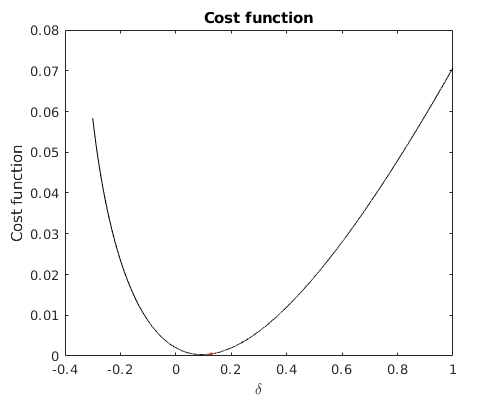

%[~, ind] = min(J);
ind = 4279;
inda = 63;
thetapl = dtheta(inda);
delta = testdelta(ind);


figure(343)
fig = figure('Position', [1 1 500 400]);
plot(testdelta, JJ(inda,:), 'k-');
hold on 
plot(testdelta(ind), JJ(inda,ind), 'r.');
xlabel('\delta')
ylabel('Cost function')
title('Cost function')

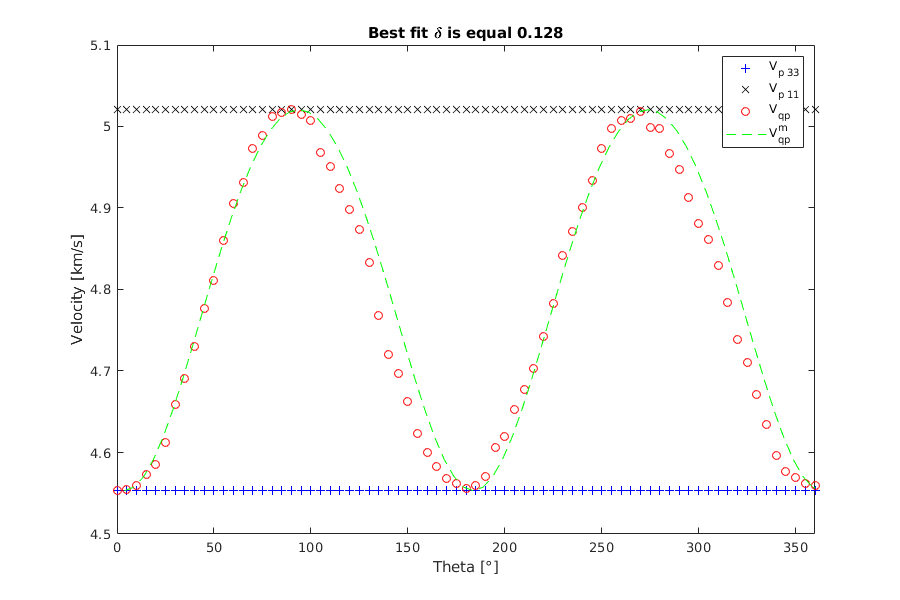




Vqp = get_Vqp_VTI(Sample,delta);

figure(3454)
fig = figure('Position', [1 1 900 600]);
plot(Sample.Theta, Sample.Vp33, '+b');
hold on
plot(Sample.Theta, Sample.Vp11, 'xk');
plot(Sample.Theta, Sample.Vqp, 'or');
hold on 
plot(Sample.Theta-thetapl, Vqp, 'g--')
axis([0 360 4.5 5.1])
xlabel('Theta [°]')
ylabel('Velocity [km/s]')
legend('V_{p 33}', 'V_{p 11}', 'V_{qp}','V_{qp}^m')
title(['Best fit \delta is equal ' num2str(delta, 3)])

## Can we improve the result? (part 1)

Define  $\psi$ - ray angle, $\theta \;$- phase angle, $v(\theta)$ - phase velocity, $V(\phi)$ - group velocity. 

In the previous part we made an assumption that in the laboratory experiment we measure $v(\theta)$.

In reality, the measured angle is much closer to ray angle, so before making the fit we have to make a correction 

for the angle: 

Our aim is to design algorithm that will work like that: $\psi \Longrightarrow \theta \Longrightarrow \mathrm{fit} \delta$

Let us introduce $\phi$ such as:  $\tan \phi = \frac{1}{v}\frac{dv}{d\theta}$. 

Then $\tan\big( \psi(\theta) \big) = \Big(\tan\theta + \tan\phi \Big)/\Big(1 - \tan\theta \tan\phi \Big) = \tan(\theta + \phi),$


$$\psi(\theta) = \theta + \phi.$$


delta = 0.15;
Theta = 0:1:360; 
Psi = get_psi_VTI(Sample,delta,Theta);

psiq = Sample.Theta; 
thetaq = interp1(Psi,Theta,psiq,'pchip');

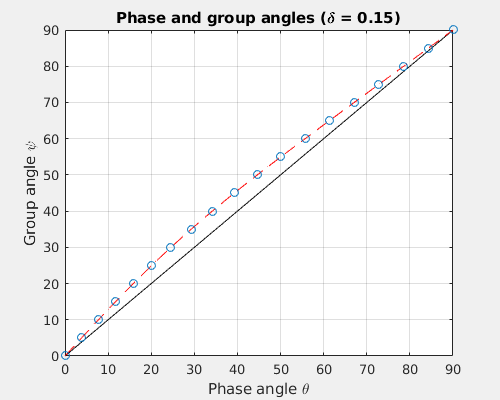

figure(34)
fig = figure('Position', [1 1 500 400]);
fig.Color = [240/255 240/255 240/255];
fig.InvertHardcopy = 'off'; 
plot(Theta,Theta,'k')
hold on 
plot(Theta,Psi,'r--')
plot(thetaq,psiq,'o');
axis([0 90 0 90])
xlabel('Phase angle \theta')
ylabel('Group angle \psi')
grid on
title(['Phase and group angles (\delta = ' num2str(delta) ')'])
print(gcf, '/home/ivan/Desktop/fig2.jpg', '-djpeg', '-r600')

## Take into account group angles

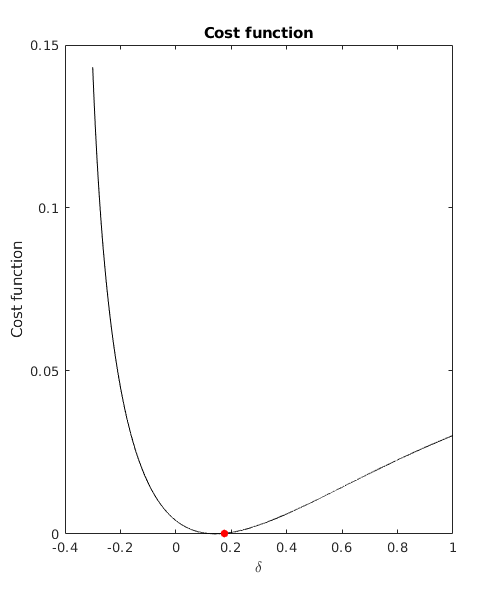

testdelta = -0.3:0.0001:1;
J = costFunction_delta_angle(Sample,testdelta);
[~, ind] = min(J);
delta = testdelta(ind);

figure(34343)
delta = 0.174; 
[~,ind] = min(abs(testdelta-delta)); 

fig = figure('Position', [1 1 500 600]);
plot(testdelta, J, 'k-');
hold on 
plot(testdelta(ind), J(ind), 'r.','MarkerSize',20);
xlabel('\delta')
ylabel('Cost function')
title('Cost function')

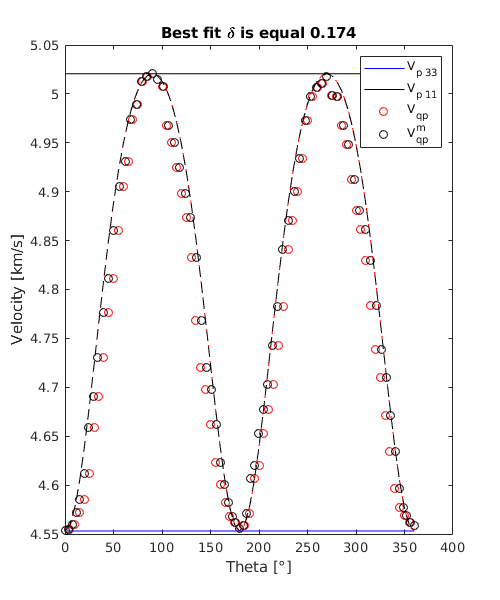

delta = 0.174; 
Theta = 0:1:360; 
Psi = get_psi_VTI(Sample,delta,Theta);
psiq = Sample.Theta; 
thetaq = interp1(Psi,Theta,psiq,'pchip');

newSample = Sample;
newSample.Theta = thetaq; 
Vqp = get_Vqp_VTI(newSample,delta);
Vqpold = get_Vqp_VTI(Sample,delta);


fig = figure('Position', [1 1 500 600]);
plot(Sample.Theta, Sample.Vp33, '-b');
hold on
plot(Sample.Theta, Sample.Vp11, '-k');
plot(Sample.Theta, Sample.Vqp, 'or');
plot(thetaq, Sample.Vqp, 'ok');
hold on 
plot(newSample.Theta, Vqp, 'r--')
plot(Sample.Theta, Vqpold, 'k--')
xlabel('Theta [°]')
ylabel('Velocity [km/s]')
legend('V_{p 33}', 'V_{p 11}', 'V_{qp}','V_{qp}^m')
title(['Best fit \delta is equal ' num2str(delta, 3)])

## Delta eror

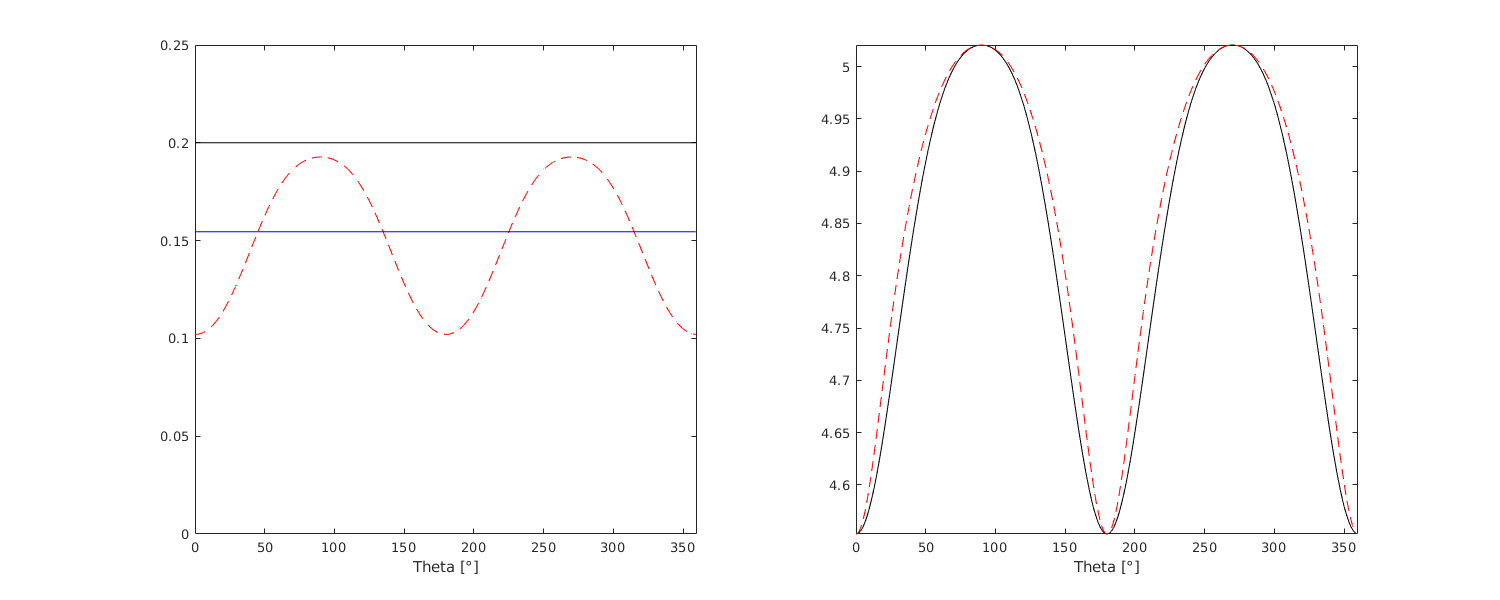

delta = 0.2;

% true
Theta = 0.1:1:360;
Theta = Theta'; 
SampleTrue = Sample;
SampleTrue.Theta = Theta; 
VqpT = get_Vqp_VTI(SampleTrue,delta);

% false
Psi = get_psi_VTI(Sample,delta,Theta);
SampleFalse = Sample;
SampleFalse.Theta = Psi; 
VqpF = get_Vqp_VTI(SampleFalse,delta);


deltaT = get_delta_VTI(SampleTrue,VqpT);
deltaF = get_delta_VTI(SampleFalse,VqpT);

figure(34343)
fig = figure('Position', [0 0 1500 600]);
subplot(1,2,1)
plot(Theta, deltaT, 'k-');
hold on 
plot(Theta, deltaF, 'r--');
plot(Theta, deltaF(46)*ones(size(Theta)), 'b-');
xlabel('Theta [°]')
axis([0 360 -0 0.25])

subplot(1,2,2)
plot(Theta, VqpT, 'k-');
hold on 
plot(Theta, VqpF, 'r--');


xlabel('Theta [°]')
axis([0 360 min(VqpT) max(VqpT)])

For presentation

Sample.Theta = 0:0.5:90; 
Delta = -0.2:0.1:0.9; 

VQP = zeros(length(Delta), length(Sample.Theta));

for i=1:length(Delta)
    VQP(i,:) = get_Vqp_VTI(Sample,Delta(i)); 
end

delta = 0.1244

delta = 0.1244

Vqptrue = get_Vqp_VTI(Sample,delta); 


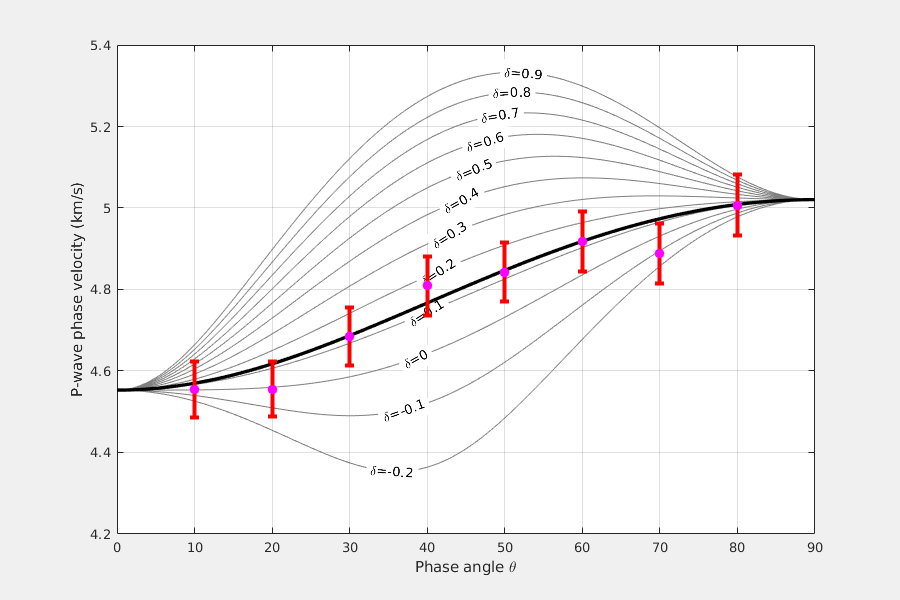


figure(8425)
fig = figure('Position', [1 1 900 600]);
fig.Color = [240/255 240/255 240/255];
fig.InvertHardcopy = 'off'; 
for i=1:length(Delta)
    h = plot(Sample.Theta, VQP(i,:), 'Color',[0.5, 0.5, 0.5]);
    mytext = ['\delta=' num2str(Delta(i))];
    text2line(h,0.38+i*0.017,0,mytext);
    hold on
end
plot(Sample.Theta, Vqptrue', 'k','LineWidth',2.5)
% plot 01
%errorbar(Sample.Theta(91),Vqptrue(91),0.05, 'Color','red','LineWidth',3)
%plot(Sample.Theta(91),Vqptrue(91),'.k','MarkerSize',25)
% plot 02
%errorbar(Sample.Theta(91),Vqptrue(91),0.2, 'Color','red','LineWidth',3)
%plot(Sample.Theta(91),Vqptrue(91),'.k','MarkerSize',25)
% plot 03
%errorbar(Sample.Theta(141),Vqptrue(141),0.2, 'Color','red','LineWidth',3)
%plot(Sample.Theta(141),Vqptrue(141),'.k','MarkerSize',25)
% plot 04

rng(11)
newVqp = Vqptrue(21:20:161)+0.035*randn(1,8);
for i =1:8
    errorbar(Sample.Theta(1+20*i),newVqp(i),newVqp(i)*0.015, 'Color','red','LineWidth',3)
end
plot(Sample.Theta(21:20:161),newVqp,'.m','MarkerSize',25)


testdelta = -0.3:0.0001:1;
nSample = Sample; 
nSample.Theta = (Sample.Theta(21:20:161))';
nSample.Vqp = newVqp';

J = costFunction_delta(nSample,testdelta);
[~, ind] = min(J);
recdelta = testdelta(ind);

Vqprec = get_Vqp_VTI(Sample,recdelta); 
%plot(Sample.Theta, Vqprec', '--b','LineWidth',2.5)


%mytext = ['\delta=' num2str(delta)];
%text2line(h,0.2,0,mytext)
xlabel('Phase angle \theta')
ylabel('P-wave phase velocity (km/s)')
grid on
set(gcf, 'InvertHardCopy', 'off');
print(gcf, '/home/ivan/Desktop/fig1.jpg', '-djpeg', '-r600');

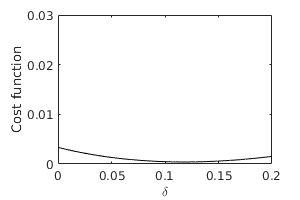



figure(842)
fig = figure('Position', [1 1 300 200]);
plot(testdelta,J, 'k')
axis([-0 0.2,0 0.03])
xlabel('\delta')
ylabel('Cost function')

uncertainty assessment

% angle error std: 3 grad  =>> error in velocity 25 m/s
% error in velocity due to measurements =>> 15 m/s
% total error: 30 m 
%                                     37 mrasurement 73
% variance for velocity error 30 m = 0.010;   0.0060
% variance for velocity error 100 m = 0.030   0.020

delta = 0.1244

delta = 0.1244

Theta = 0:1:360;
Sample.Theta = Theta;
Vqptrue = get_Vqp_VTI(Sample,delta); 

VqpT = Vqptrue(1:5:end);
TheT = Theta(1:5:end);

for i=1:1:1000
    VqpE = VqpT+0.03*randn(1,73);

    testdelta = -0.3:0.0001:1;
    nSample = Sample; 
    nSample.Theta = TheT';
    nSample.Vqp = VqpE';
    
    J = costFunction_delta(nSample,testdelta);
    [~, ind] = min(J);
    Rdelta(i) = testdelta(ind);
end
    
    
  